% ========================================================
% === SCRIPT COMPLETO: PIPELINE SVD_BC + YALE CNN SVD  ===
% ========================================================
clear; clc; close all;
tic;

%% ----------------------------------------------------------------
%% 0) SETUP AMBIENTE & CARTELLA RISULTATI
%% ----------------------------------------------------------------
projectRoot  = pwd;
addpath(genpath(projectRoot));
results_path = fullfile(projectRoot,'results_yale_cnn_svd');
if ~exist(results_path,'dir')
    mkdir(results_path);
end

%% ----------------------------------------------------------------
%% 1) HYPERPARAMETERS
%% ----------------------------------------------------------------
epochs        = 40;        % massimo epoche
base_lr       = 0.01;      % learning rate iniziale
lambda        = 1e-4;      % peso L2
dropout_rate  = 0.2;       % dropout rate
batch_size    = 32;        % mini-batch size
patience      = 5;         % early stopping

%% ----------------------------------------------------------------
%% 2) CARICAMENTO YALE & NORMALIZZAZIONE
%% ----------------------------------------------------------------
fprintf('>>> Caricamento dataset Yale...\n');

>>> Caricamento dataset Yale...


load('dataset/volti_dataset_Yale.mat');   % A (m×n), labels
A      = double(A)/255;
labels = labels(:);
[img_h, img_w, ~] = deal(112,92,[]);
[m, n] = size(A);
num_classes = max(labels);

% reshape in [H×W×N]
imgs_raw = reshape(A, img_h, img_w, []);
% per-pixel normalization
mean_img = mean(imgs_raw,3);
std_img  = std(imgs_raw,0,3) + eps;
imgs_norm = (imgs_raw - mean_img) ./ std_img;

%% ----------------------------------------------------------------
%% 3) SVD_BC: MEAN FACE, CENTRATURA, SVD
%% ----------------------------------------------------------------
tol   = 1e-4;
maxit = 1000;
energy_threshold = 0.95;

fprintf('>>> Calcolo volto medio e centratura...\n');

>>> Calcolo volto medio e centratura...


mean_face   = mean(A,2);
A_centered  = A - mean_face;
save(fullfile(results_path,'mean_face.mat'),'mean_face');

fprintf('>>> Esecuzione SVD_BC...\n');

>>> Esecuzione SVD_BC...


[U,S,~] = svd_BC(A_centered,tol,maxit);

   [svd_BC] costruisco ATA...
   [svd_BC] chiamo qr_eig su 165x165 (tol=1.0e-04,maxit=1000)...
         [qr_eig] deflazione k=165 ... 

iter=1001 time=2.54 s
         [qr_eig] deflazione k=164 ... 

iter=1001 time=2.09 s
         [qr_eig] deflazione k=163 ... 

iter=1001 time=2.16 s
         [qr_eig] deflazione k=162 ... iter=338 time=0.72 s
         [qr_eig] deflazione k=161 ... 

iter=1001 time=2.16 s
         [qr_eig] deflazione k=160 ... iter=309 time=0.50 s
         [qr_eig] deflazione k=159 ... 

iter=1001 time=2.13 s
         [qr_eig] deflazione k=158 ... 

iter=1001 time=4.42 s
         [qr_eig] deflazione k=157 ... 

iter=1001 time=2.51 s
         [qr_eig] deflazione k=156 ... iter=765 time=1.75 s
         [qr_eig] deflazione k=155 ... 

iter=1001 time=1.94 s
         [qr_eig] deflazione k=154 ... 

iter=1001 time=2.07 s
         [qr_eig] deflazione k=153 ... 

iter=1001 time=1.94 s
         [qr_eig] deflazione k=152 ... 

iter=1001 time=1.66 s
         [qr_eig] deflazione k=151 ... 

iter=1001 time=1.64 s
         [qr_eig] deflazione k=150 ... 

iter=1001 time=1.57 s
         [qr_eig] deflazione k=149 ... 

iter=1001 time=1.56 s
         [qr_eig] deflazione k=148 ... 

iter=1001 time=1.36 s
         [qr_eig] deflazione k=147 ... 

iter=1001 time=1.62 s
         [qr_eig] deflazione k=146 ... 

iter=1001 time=1.80 s
         [qr_eig] deflazione k=145 ... 

iter=1001 time=3.69 s
         [qr_eig] deflazione k=144 ... 

iter=1001 time=2.45 s
         [qr_eig] deflazione k=143 ... 

iter=1001 time=1.69 s
         [qr_eig] deflazione k=142 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=141 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=140 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=139 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=138 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=137 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=136 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=135 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=134 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=133 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=132 ... 

iter=1001 time=0.73 s
         [qr_eig] deflazione k=131 ... 

iter=1001 time=0.69 s
         [qr_eig] deflazione k=130 ... 

iter=1001 time=0.67 s
         [qr_eig] deflazione k=129 ... 

iter=1001 time=0.66 s
         [qr_eig] deflazione k=128 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=127 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=126 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=125 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=124 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=123 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=122 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=121 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=120 ... iter=90 time=0.05 s
         [qr_eig] deflazione k=119 ... 

iter=1001 time=0.66 s
         [qr_eig] deflazione k=118 ... 

iter=1001 time=0.57 s
         [qr_eig] deflazione k=117 ... 

iter=1001 time=0.58 s
         [qr_eig] deflazione k=116 ... 

iter=1001 time=0.54 s
         [qr_eig] deflazione k=115 ... 

iter=1001 time=0.57 s
         [qr_eig] deflazione k=114 ... iter=2 time=0.00 s
         [qr_eig] deflazione k=113 ... iter=514 time=0.30 s
         [qr_eig] deflazione k=112 ... 

iter=1001 time=0.50 s
         [qr_eig] deflazione k=111 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=110 ... 

iter=1001 time=0.49 s
         [qr_eig] deflazione k=109 ... 

iter=1001 time=0.50 s
         [qr_eig] deflazione k=108 ... 

iter=1001 time=0.48 s
         [qr_eig] deflazione k=107 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=106 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=105 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=104 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=103 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=102 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=101 ... iter=989 time=0.42 s
         [qr_eig] deflazione k=100 ... 

iter=1001 time=0.42 s
         [qr_eig] deflazione k=99 ... 

iter=1001 time=0.41 s
         [qr_eig] deflazione k=98 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=97 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=96 ... 

iter=1001 time=0.38 s
         [qr_eig] deflazione k=95 ... 

iter=1001 time=0.40 s
         [qr_eig] deflazione k=94 ... 

iter=1001 time=0.38 s
         [qr_eig] deflazione k=93 ... 

iter=1001 time=0.37 s
         [qr_eig] deflazione k=92 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=91 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=90 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=89 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=88 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=87 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=86 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=85 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=84 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=83 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=82 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=81 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=80 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=79 ... 

iter=1001 time=0.31 s
         [qr_eig] deflazione k=78 ... 

iter=1001 time=0.28 s
         [qr_eig] deflazione k=77 ... iter=344 time=0.09 s
         [qr_eig] deflazione k=76 ... 

iter=1001 time=0.27 s
         [qr_eig] deflazione k=75 ... 

iter=1001 time=0.27 s
         [qr_eig] deflazione k=74 ... 

iter=1001 time=0.26 s
         [qr_eig] deflazione k=73 ... 

iter=1001 time=0.26 s
         [qr_eig] deflazione k=72 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=71 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=70 ... iter=906 time=0.21 s
         [qr_eig] deflazione k=69 ... 

iter=1001 time=0.23 s
         [qr_eig] deflazione k=68 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=67 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=66 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=65 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=64 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=63 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=62 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=61 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=60 ... 

iter=1001 time=0.19 s
         [qr_eig] deflazione k=59 ... 

iter=1001 time=0.19 s
         [qr_eig] deflazione k=58 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=57 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=56 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=55 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=54 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=53 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=52 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=51 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=50 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=49 ... iter=2 time=0.00 s
         [qr_eig] deflazione k=48 ... 

iter=1001 time=0.14 s
         [qr_eig] deflazione k=47 ... 

iter=1001 time=0.13 s
         [qr_eig] deflazione k=46 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=45 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=44 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=43 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=42 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=41 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=40 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=39 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=38 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=37 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=36 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=35 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=34 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=33 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=32 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=31 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=30 ... iter=0 time=0.00 s
         

save(fullfile(results_path,'svd_data.mat'),'U','S');

%% ----------------------------------------------------------------
%% 4) RICOSTRUZIONE LOW-RANK + NORMALIZZAZIONE
%% ----------------------------------------------------------------
sig2   = diag(S).^2;
energy = cumsum(sig2)/sum(sig2);
k      = find(energy>=energy_threshold,1);
fprintf('>>> K = %d (%.1f%% energia)\n',k,100*energy(k));

>>> K = 163 (96.4% energia)



A_rec   = U(:,1:k)*S(1:k,1:k)*U(:,1:k)' + mean_face;  % low-rank approx
imgs_rec = reshape(A_rec,img_h,img_w,[]);

% per-pixel normalize
mean_img = mean(imgs_rec,3);
std_img  = std(imgs_rec,0,3) + eps;
imgs = (imgs_rec - mean_img) ./ std_img;

%% ----------------------------------------------------------------
%% 5) SPLIT 5-vs-5 TRAIN/TEST
%% ----------------------------------------------------------------
train_idx = []; test_idx = [];
for s=1:num_classes
    idx_s = find(labels==s);
    idx_s = idx_s(randperm(numel(idx_s)));
    train_idx = [train_idx; idx_s(1:5)];
    test_idx  = [test_idx;  idx_s(6:end)];
end
imgs_train_base = imgs(:,:,train_idx);
y_train_base    = labels(train_idx)';
imgs_test       = imgs(:,:,test_idx);
y_test          = labels(test_idx)';

%% ----------------------------------------------------------------
%% 6) DATA AUGMENTATION + SPLIT VALIDATION 20%
%% ----------------------------------------------------------------
[imgs_train_aug,y_train_aug] = augment_data(imgs_train_base,y_train_base);
N_aug = size(imgs_train_aug,3);
perm_aug = randperm(N_aug);
val_n  = round(0.2*N_aug);
val_idx  = perm_aug(1:val_n);
trn_idx  = perm_aug(val_n+1:end);

imgs_train = imgs_train_aug(:,:,trn_idx);
y_train    = y_train_aug(trn_idx);
imgs_val   = imgs_train_aug(:,:,val_idx);
y_val      = y_train_aug(val_idx);

Y_train = onehot_encode(y_train,num_classes);
Y_val   = onehot_encode(y_val,  num_classes);

%% 5) CNN ARCHITECTURE (16-32-64)
f1=3; n_f1=16;
f2=3; n_f2=32;
f3=3; n_f3=64;
pool=2;

conv1_h = img_h - f1 + 1;  conv1_w = img_w - f1 + 1;
pool1_h = floor(conv1_h/pool); pool1_w = floor(conv1_w/pool);
conv2_h = pool1_h - f2 + 1;  conv2_w = pool1_w - f2 + 1;
pool2_h = floor(conv2_h/pool); pool2_w = floor(conv2_w/pool);
conv3_h = pool2_h - f3 + 1;  conv3_w = pool2_w - f3 + 1;
pool3_h = floor(conv3_h/pool); pool3_w = floor(conv3_w/pool);

fc_input_size = pool3_h * pool3_w * n_f3;
fprintf('[DEBUG] fc_input_size = %d\n', fc_input_size);

[DEBUG] fc_input_size = 6912



% He initialisation
filters1 = randn(f1,f1,n_f1)               * sqrt(2/(f1*f1*n_f1)); bias1 = zeros(n_f1,1);
filters2 = randn(f2,f2,n_f2,n_f1)          * sqrt(2/(f2*f2*n_f2)); bias2 = zeros(n_f2,1);
filters3 = randn(f3,f3,n_f3,n_f2)          * sqrt(2/(f3*f3*n_f3)); bias3 = zeros(n_f3,1);
W_fc     = randn(num_classes, fc_input_size)* sqrt(2/fc_input_size);
b_fc     = zeros(num_classes,1);

%% 6) TRAINING LOOP ----------------------------------------------------
N_train   = size(imgs_train,3);
N_val     = size(imgs_val,3);
num_batches = floor(N_train / batch_size);

loss_history = zeros(1, epochs);
acc_history  = zeros(1, epochs);
val_loss_hist= zeros(1, epochs);
val_acc_hist = zeros(1, epochs);

best_val_acc = 0;  no_improve = 0;

for epoch = 1:epochs
    lr   = base_lr;                     
    perm = randperm(N_train);
    total_loss = 0;   correct = 0;

    for b = 1:num_batches
        idx_b = perm((b-1)*batch_size + (1:batch_size));
        Xb = imgs_train(:,:,idx_b);
        Yb = Y_train(:,idx_b);
        Nb = size(Xb,3);

        % azzera gradienti batch
        dW1=0*filters1; db1=0*bias1;
        dW2=0*filters2; db2=0*bias2;
        dW3=0*filters3; db3=0*bias3;
        dWfc=zeros(size(W_fc)); dbfc=zeros(size(b_fc));

        for i = 1:Nb
            x = Xb(:,:,i);
            y_true = Yb(:,i);

            % --- forward ---
            [c1,cache1] = conv2d_forward(x,filters1,bias1); r1 = max(c1,0);
            [p1,mask1]  = maxpool2d_forward(r1,pool);

            [c2,cache2] = conv2d_forward_multi(p1,filters2,bias2); r2 = max(c2,0);
            [p2,mask2]  = maxpool2d_forward(r2,pool);

            [c3,cache3] = conv2d_forward_multi(p2,filters3,bias3); r3 = max(c3,0);
            [p3,mask3]  = maxpool2d_forward(r3,pool);

            x_fc = reshape(p3,[],1);           % flatten
            z = W_fc * x_fc + b_fc;
            z = z - max(z);                    % stabilità soft-max
            y_pred = exp(z) / sum(exp(z));

            % loss & accuracy
            total_loss = total_loss - sum(y_true .* log(y_pred + 1e-12));
            if find(y_pred==max(y_pred)) == find(y_true); correct=correct+1; end

            % --- backward ---
            dz = y_pred - y_true;                 % [C×1]
            dWfc_b = dz * x_fc';   dbfc_b = dz;
            dx_fc  = W_fc' * dz;                  % [fc_input_size]

            dp3 = reshape(dx_fc, size(p3));
            dr3 = maxpool2d_backward(dp3, mask3);
            dc3 = dr3 .* (c3 > 0);
            [dp2, dW3_b, db3_b] = conv2d_backward_multi(p2,filters3,dc3,cache3);

            dr2 = maxpool2d_backward(dp2, mask2);
            dc2 = dr2 .* (c2 > 0);
            [dp1, dW2_b, db2_b] = conv2d_backward_multi(p1,filters2,dc2,cache2);

            dr1 = maxpool2d_backward(dp1, mask1);
            dc1 = dr1 .* (c1 > 0);
            [~, dW1_b, db1_b] = conv2d_backward(x,filters1,dc1,cache1);

            % accumula gradienti
            dWfc=dWfc+dWfc_b; dbfc=dbfc+dbfc_b;
            dW3 =dW3 +dW3_b;  db3 =db3 +db3_b;
            dW2 =dW2 +dW2_b;  db2 =db2 +db2_b;
            dW1 =dW1 +dW1_b;  db1 =db1 +db1_b;

        end

        % --- update pesi (media batch) ---
        filters1 = filters1 - lr * dW1/Nb;
        bias1    = bias1    - lr * db1/Nb;
        filters2 = filters2 - lr * dW2/Nb;
        bias2    = bias2    - lr * db2/Nb;
        filters3 = filters3 - lr * dW3/Nb;
        bias3    = bias3    - lr * db3/Nb;
        W_fc     = W_fc     - lr * dWfc/Nb;
        b_fc     = b_fc     - lr * dbfc/Nb;
    end % batch loop

    loss_history(epoch) = total_loss / N_train;
    acc_history(epoch)  = correct / N_train * 100;

    % ---------- VALIDATION ----------
    correct_val = 0; val_loss = 0;
    for j = 1:N_val
        x = imgs_val(:,:,j);   y_true = Y_val(:,j);
        [c1,~] = conv2d_forward(x,filters1,bias1); r1 = max(c1,0);
        [p1,~] = maxpool2d_forward(r1,pool);
        [c2,~] = conv2d_forward_multi(p1,filters2,bias2); r2 = max(c2,0);
        [p2,~] = maxpool2d_forward(r2,pool);
        [c3,~] = conv2d_forward_multi(p2,filters3,bias3); r3 = max(c3,0);
        [p3,~] = maxpool2d_forward(r3,pool);
        z = W_fc*reshape(p3,[],1)+b_fc;  z=z-max(z);  y_pred = exp(z)/sum(exp(z));
        val_loss = val_loss - sum(y_true.*log(y_pred+1e-12));
        if find(y_pred==max(y_pred))==find(y_true); correct_val=correct_val+1; end
    end
    val_loss_hist(epoch) = val_loss / N_val;
    val_acc_hist(epoch)  = correct_val / N_val * 100;

    fprintf('[E%02d] loss %.3f acc %.2f | val-loss %.3f acc %.2f\n',...
        epoch, loss_history(epoch), acc_history(epoch), ...
        val_loss_hist(epoch), val_acc_hist(epoch));

    % early-stopping
    if val_acc_hist(epoch) > best_val_acc
        best_val_acc = val_acc_hist(epoch);
        best = {filters1,bias1,filters2,bias2,filters3,bias3,W_fc,b_fc};
        no_improve = 0;
    else
        no_improve = no_improve + 1;
        if no_improve >= patience
            fprintf('Early stop! (no val-improve)\n'); break;
        end
    end
end % epoch loop

[E01] loss 2.695 acc 6.56 | val-loss 2.704 acc 5.78
[E02] loss 2.681 acc 7.22 | val-loss 2.692 acc 6.22
[E03] loss 2.665 acc 8.00 | val-loss 2.674 acc 6.22
[E04] loss 2.641 acc 9.00 | val-loss 2.651 acc 11.11
[E05] loss 2.610 acc 10.78 | val-loss 2.609 acc 14.22
[E06] loss 2.564 acc 14.56 | val-loss 2.546 acc 18.67
[E07] loss 2.484 acc 18.89 | val-loss 2.435 acc 23.11
[E08] loss 2.357 acc 18.89 | val-loss 2.284 acc 27.11
[E09] loss 2.226 acc 21.78 | val-loss 2.175 acc 24.44
[E10] loss 2.145 acc 23.33 | val-loss 2.192 acc 28.89
[E11] loss 2.070 acc 27.00 | val-loss 2.143 acc 28.00
[E12] loss 2.060 acc 25.56 | val-loss 2.006 acc 30.67
[E13] loss 1.991 acc 26.11 | val-loss 1.965 acc 28.00
[E14] loss 1.931 acc 29.22 | val-loss 1.919 acc 26.67
[E15] loss 1.903 acc 27.78 | val-loss 1.861 acc 28.89
[E16] loss 1.846 acc 30.56 | val-loss 1.878 acc 31.11
[E17] loss 1.800 acc 32.89 | val-loss 1.931 acc 31.11
[E18] loss 1.829 acc 29.67 | val-loss 1.843 acc 26.67
[E19] loss 1.769 acc 32.22 | val-lo

Early stop! (no val-improve)


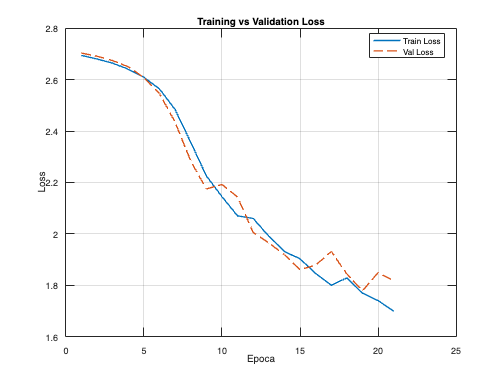


% --- Plot Training vs Validation Loss ---
figure('Name','Loss: Training vs Validation','NumberTitle','off');
plot(1:epoch, loss_history(1:epoch), '-' , 'LineWidth',1.5); hold on;
plot(1:epoch, val_loss_hist(1:epoch), '--', 'LineWidth',1.5);
xlabel('Epoca');
ylabel('Loss');
title('Training vs Validation Loss');
legend('Train Loss','Val Loss','Location','best');
grid on;

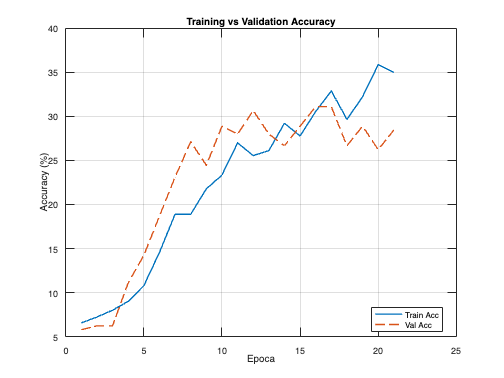


% --- Plot Training vs Validation Accuracy ---
figure('Name','Accuracy: Training vs Validation','NumberTitle','off');
plot(1:epoch, acc_history(1:epoch), '-' , 'LineWidth',1.5); hold on;
plot(1:epoch, val_acc_hist(1:epoch), '--', 'LineWidth',1.5);
xlabel('Epoca');
ylabel('Accuracy (%)');
title('Training vs Validation Accuracy');
legend('Train Acc','Val Acc','Location','best');
grid on;



%% 7) TEST ----------------------------------------------------------------
[filters1,bias1,filters2,bias2,filters3,bias3,W_fc,b_fc] = best{:};
correct_test = 0;  N_test = size(imgs_test,3);

for i = 1:N_test
    x = imgs_test(:,:,i);
    [c1,~] = conv2d_forward(x,filters1,bias1); r1=max(c1,0);
    [p1,~] = maxpool2d_forward(r1,pool);
    [c2,~] = conv2d_forward_multi(p1,filters2,bias2); r2=max(c2,0);
    [p2,~] = maxpool2d_forward(r2,pool);
    [c3,~] = conv2d_forward_multi(p2,filters3,bias3); r3=max(c3,0);
    [p3,~] = maxpool2d_forward(r3,pool);
    z = W_fc*reshape(p3,[],1)+b_fc;  z=z-max(z);  y_pred = exp(z)/sum(exp(z));
    if find(y_pred==max(y_pred)) == y_test(i); correct_test = correct_test + 1; end
end
fprintf('\n*** TEST ACCURACY: %.2f %% ***\n', correct_test / N_test * 100);


*** TEST ACCURACY: 30.00 % ***




fprintf('>>> Totale: %.2f s\n',toc);

>>> Totale: 3832.71 s


## 8) SUPPORT FUNCTIONS

function Y = onehot_encode(labels, num_classes)
    labels = labels(:)';               % vettore riga
    N = numel(labels);
    Y = zeros(num_classes, N);
    idx = sub2ind(size(Y), labels, 1:N);
    Y(idx) = 1;
end

function dx = maxpool2d_backward(dout, mask)
% BACKWARD del max-pooling (maschere = cell array binarie)
    F = numel(mask);
    [H,W]   = size(mask{1});
    [Hp,Wp] = size(dout(:,:,1));
    ph = floor(H/Hp);  pw = floor(W/Wp);
    dx = zeros(H,W,F);
    for f = 1:F
        m = mask{f};  d = dout(:,:,f);
        for i = 1:Hp
            for j = 1:Wp
                rs = (i-1)*ph+1; re = i*ph;
                cs = (j-1)*pw+1; ce = j*pw;
                dx(rs:re, cs:ce, f) = m(rs:re, cs:ce) * d(i,j);
            end
        end
    end
end

